Tyler Barbero

SIO175 HW4: Fourier Analysis

**Problem 1**

clc;clear;close;clf
load('CMI_data.mat')
readme

readme = 't: time, pn: pressure at sensor n, e7: surface elevation at sensor 7'

CMI variables are 5400x200, 5400 seconds by 200 3-hour bursts.

5400 seconds = 90 minutes

900 seconds = 15 minutes

**Problem 2: **Reshape the data into 15-minute bursts.

15-minutes*60sec/1min = 900 seconds

90-min burst / 15-min bursts = 6

So we reshape 5400 sec x 200 3-hr bursts into

900 sec x 200(6) 3-hr bursts = 900sec x 1200bursts

Reshape will go down the columns of the data and reshape into specified matrix size

3 hour burst same as 1:18  3 6*15=90 minute bursts 

t = reshape(CMI.t,900,1200);
p2 = reshape(CMI.p2,900,1200);
p3 = reshape(CMI.p3,900,1200);
p4 = reshape(CMI.p4,900,1200);
p6 = reshape(CMI.p6,900,1200);
p7 = reshape(CMI.p7,900,1200);
e7 = reshape(CMI.e7,900,1200);

**Problem 3: **		

For each 15-min burst, compute the significant wave height in the sea/swell (f > 1/25 Hz) and infragravity (f <= 1/25 Hz) frequency bands from the pressure (p2, p3, p4, p6) and surface elevation series (e7). Plot the significant wave height time series.

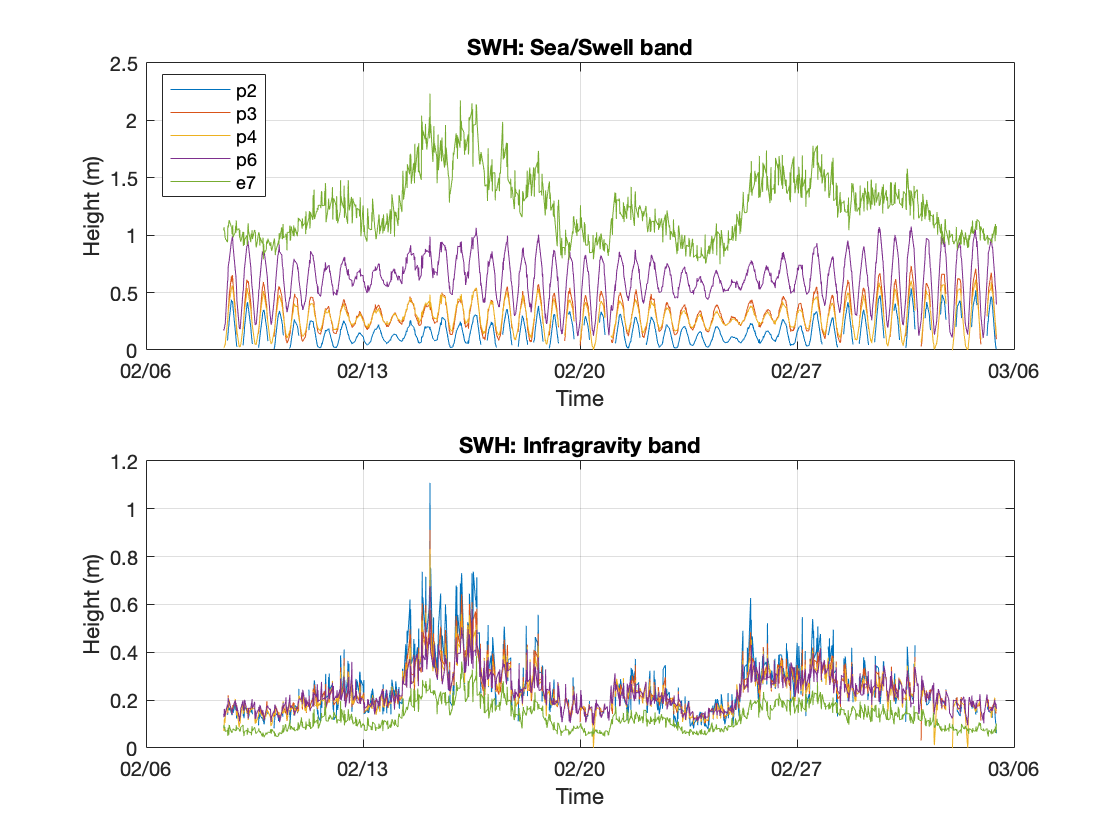

clf
for i=2:7
    try
eval(['Xe = fft([p' num2str(i) ']);'])
    catch;continue % if var doesnt, exist skip
    end
if i==7;eval(['Xe = fft([e' num2str(i) ']);']);end

Xe = fftshift(Xe); 
[N,Nc]= size(Xe);
dt = 1;
fN = 1/(2*dt); % Nyquist (highest) frequency
df = 1/(N*dt); % lowest frequency
f = -fN:df:(fN-df); % create frequency array

tmp1 = find(abs(f)>0.04); % sea/swell band
Xess = Xe(tmp1,:);
varss = (1/(N*(N-1)))*sum(abs(Xess).^2); %two norm, normalized
SWHss = sqrt(varss)*4;
if i==7;[val,indd]=max(SWHss);end

subplot(2,1,1)
plot(mean(t),SWHss);hold on;datetick;grid
xlabel('Time');ylabel('Height (m)')
title('SWH: Sea/Swell band')
if i==7;legend('p2','p3','p4','p6','e7','location','NW');end

tmp2 = find(abs(f)<=0.04 & abs(f)>0); % infragravity wave band
Xeig = Xe(tmp2,:);
varig = (1/(N*(N-1)))*sum(abs(Xeig).^2); %two norm, normalized
SWHig = sqrt(varig)*4;

subplot(2,1,2)
plot(mean(t),SWHig);hold on;datetick;grid
xlabel('Time');ylabel('Height (m)')
title('SWH: Infragravity band')
end

**Problem 4: **

Compute the wave setup as the difference in 15-min mean pressure between p2 and p7. Remove the time mean from the wave setup and plot the setup time series. 		

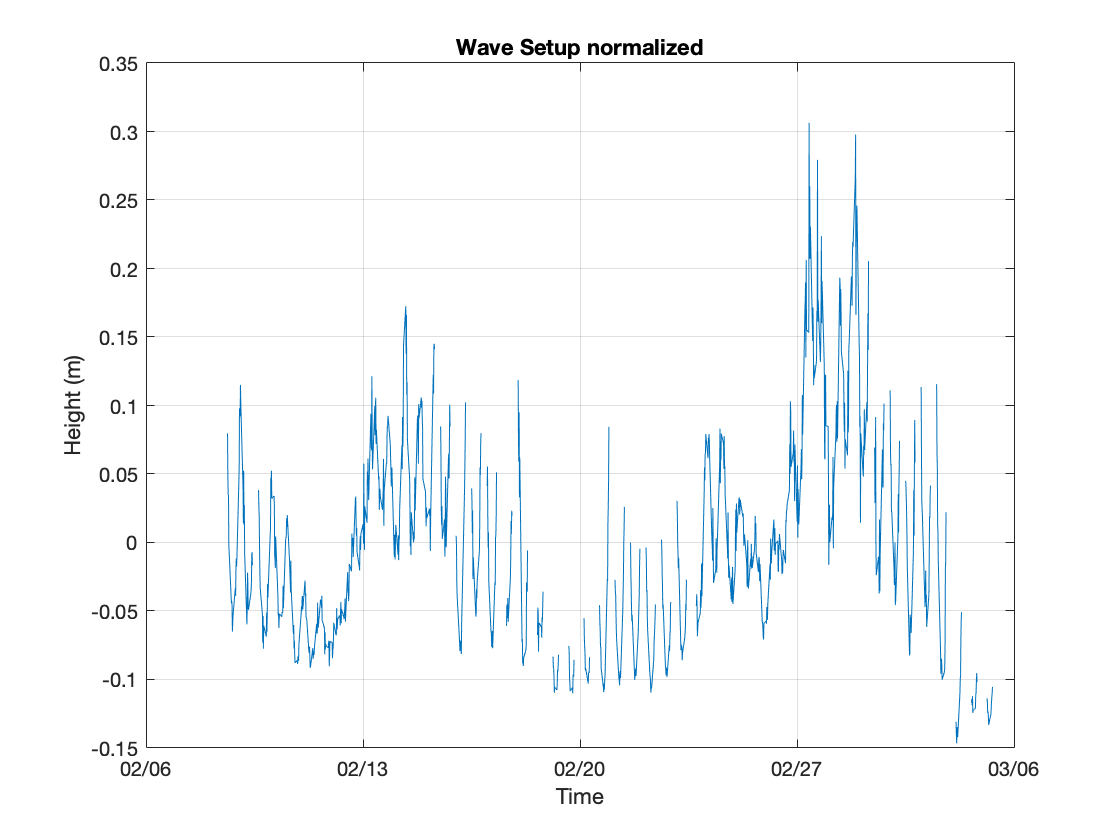

clf
wave_setup = nanmean(p2)-nanmean(p7); % remove tidal signal
wave_setup = wave_setup - nanmean(wave_setup); % take out mean(wave setup) - 0 mean
plot(mean(t),wave_setup);datetick;grid
xlabel('Time')
ylabel('Height (m)')
title('Wave Setup normalized')

**Problem 5:**

Compute the 15-min mean water depth at p7 as a proxy for the tidal height. Plot the time series.

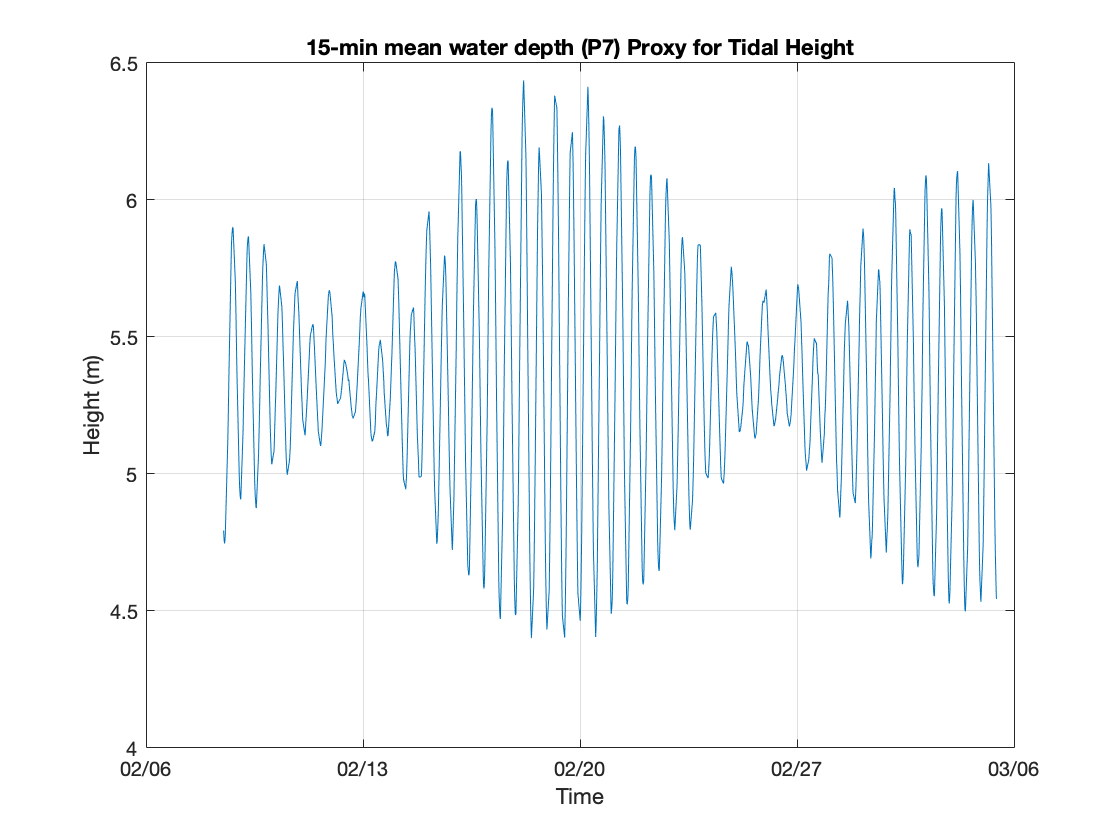

clf
plot(mean(t),nanmean(p7));grid
datetick
xlabel('Time')
ylabel('Height (m)')
title('15-min mean water depth (P7) Proxy for Tidal Height')

**Problem 6:**

For the significant wave heights and wave setup time series on the reef, which appear to be related to sea-swell significant wave height at sensor 7 (i.e., the incident wave forcing)? Which are related to the tidal elevation?				

The significant wave height infragravity bands appear to be related to the sea/swell significant wave height at sensor e7; The SWH IG plots look like the signal of the sea/swell SWH at e7.

The significant wave height sea/swell band plots from sensors on the reef p2,p3,p4,p6 look to be related to the tidal elevation.

**Problem 7:**	

For the wave burst with maximum sea-swell significant wave height at e7, plot (on the same plot) the autospectra for p2, p3, p4, p6, and e7. 										

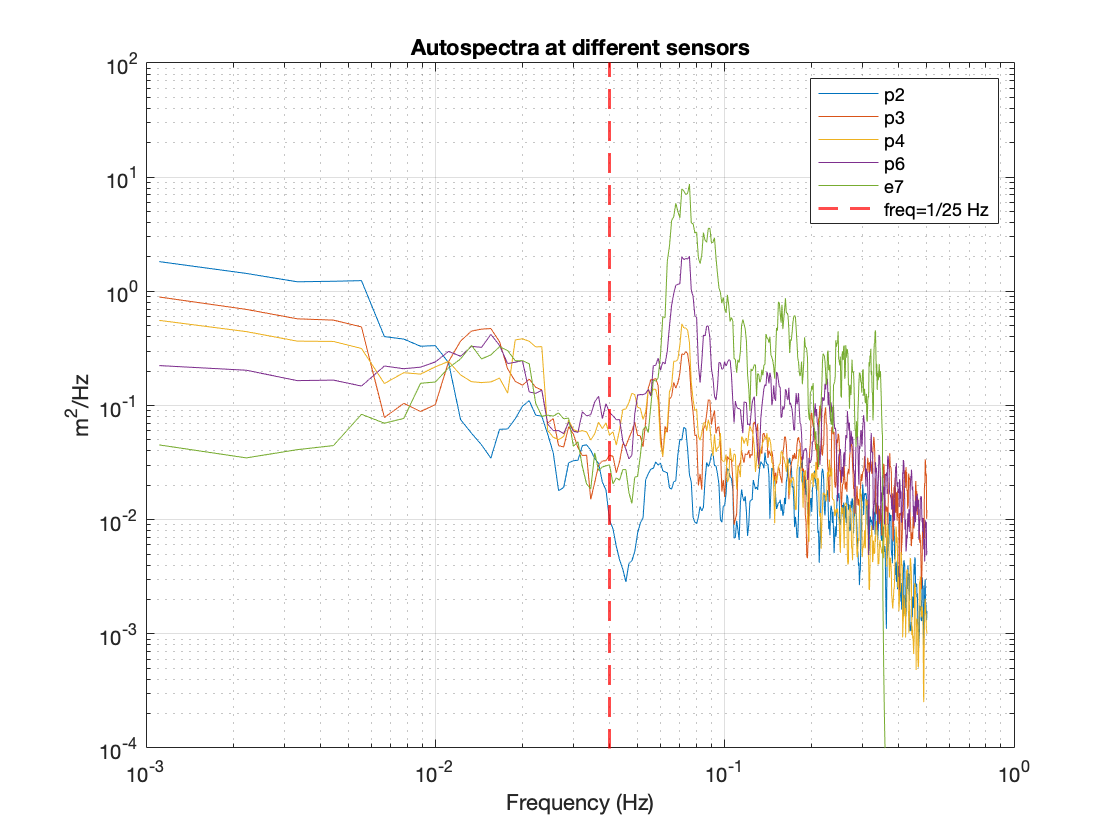

clf
% get maximum sea-swell significnat wave height at e7
% ind gets index from max seaswell time which I got in Problem 3
% choose Averaging term = 15, decently smooths out signal
[S2,f,ubound,lbound] = autospec(p2(:,indd),1,5,0.05);
[S3,f,ubound,lbound] = autospec(p3(:,indd),1,5,0.05);
[S4,f,ubound,lbound] = autospec(p4(:,indd),1,5,0.05);
[S6,f,ubound,lbound] = autospec(p6(:,indd),1,5,0.05);
[S7,f,ubound,lbound] = autospec(e7(:,indd),1,5,0.05);
loglog(f,S2,f,S3,f,S4,f,S6,f,S7);grid
xlabel('Frequency (Hz)')
ylabel('m^2/Hz')
title('Autospectra at different sensors')
xline(0.04,'--r','linewidth',1.5);
legend('p2','p3','p4','p6','e7','freq=1/25 Hz')
ylim([10^-4 10^2])

*Describe how energy in the sea/swell (f > 1/25 Hz) and infragravity (f <= 1/25 Hz) frequency bands varies across the reef. *

In the sea/swell band, we see most of the energy lies in e7 which is the farthest sensor from the reef. The energy is then distributed across the rest of the sensors on the reef, with p2 showing the lowest energy, due to it being farthest away from the reef edge. I think this makes sense the swell breaks on the reef and most of the energy should be found in e7 which we do.

In the infragravity band, we see similar signals as in the sea swell band up until around freq = 10^-2 Hz, where this flips. P2 illustrates  the most energy which descends in order with e7 having the lowest energy.

Part of the energy from the swell band (we see a decrease in sea/swell) transfers to the infragravity band on the reef. 